# Lab 2 - 1.

## Init

clear;

## R1.a)

M = 512;
w_0 = 5.2*2*pi/M; % (rad)
% Create signal x
n = (0:M-1)';
x = 5*cos(w_0*n+1)+2*cos(2*w_0*n+2)+3*cos(5*w_0*n+3);

## R1.b)

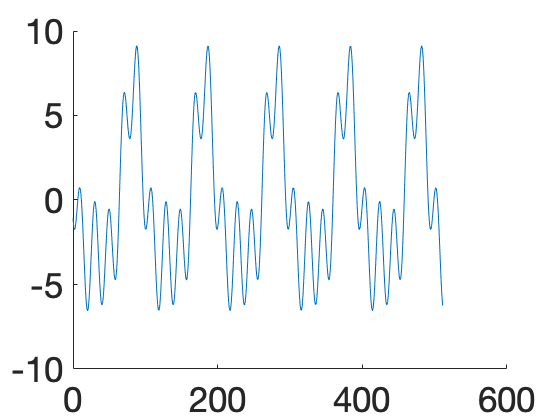

% plot x(n)
figure;
hold on;
set(gca,'FontSize',35);
plot(0:M-1,x);

The expression used to obtain x is a sim of sinusoidal signals with differents periods. It it, thus expected, that x is a peiodic signal with a period of the least integer common multiple of the periods of the sinusoids, it it exists. That is, the period of x is $T=m.i.c.m.(2\pi/(\omega_0),2\pi/(2\omega_0),2\pi/(5\omega_0)) = 1280$. Thus, although it appears that from the plot above that the period of $x(n)$ is smaller, in discrete-time it is actually not. 

## R1.c)

N = 512;
[absX,angX,f] = dft_custom(x,N);
size(absX)

ans =    257     1


size(f)

ans =    256     1


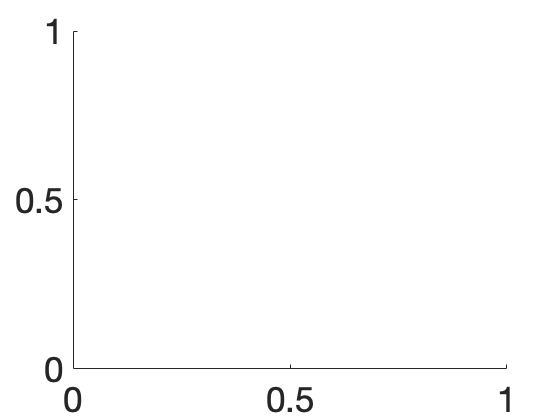

% dft = fft(x,N);
% X = fftshift(2*dft)/M;
% f =2*pi*(-N/2:(N-1)/2)'/N;
% 
% absX = abs(X);
% angX = angle(X);

figure;
hold on;
set(gca,'FontSize',35);

plot(f,absX)

Error using plot
Vectors must be the same length.

figure;
hold on;
set(gca,'FontSize',35);
plot(f,angX)

## R1.d)

[magpks,idxpks] = findpeaks(absX);
magpks = magpks(4:6);
idxpks = idxpks(4:6);
idxpks

idxpks =    262
   267
   283


magpks

magpks =     4.5886
    1.5735
    2.9577


fpks = f(idxpks)

fpks =     0.0614
    0.1227
    0.3191


angpks = angX(idxpks)

angpks =     1.6611
   -2.8673
    3.0211


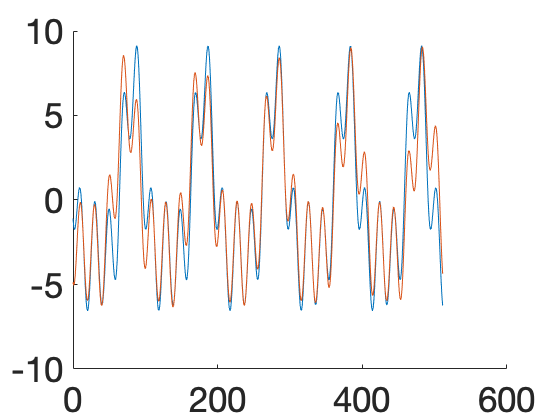

xr = zeros(M,1);
for p = 1:3
    xr = xr + magpks(p)*exp(1i*angpks(p))*exp(1i*fpks(p)*n);
    %xr = xr + magpks(p)*cos(angpks(p)+fpks(p)*n);
end 
xr = real(xr);

figure;
hold on;
set(gca,'FontSize',35);
plot(0:M-1,x);
plot(0:M-1,xr);

## R1.f)

N = 1024;
dft = fft(x,N);
X=fftshift(2*dft)/M;
f =2*pi*(-N/2:(N-1)/2)'/N;

absX = abs(X);
angX = angle(X);

% Find peaks
[magpks_aux,idxpks_aux] = findpeaks(absX(N/2:end));
for p = 1:3
    [magpks(p), idxpks(p)] = max(magpks_aux);
    magpks_aux(idxpks(p))      = -Inf;
end
idxpks = idxpks_aux(idxpks);
magpks

magpks =     4.5886
    2.9577
    1.9490


fpks = f(N/2-1+idxpks)

fpks =     0.0614
    0.3191
    0.1289


angpks = angX(N/2-1+idxpks)

angpks =     1.6611
    3.0211
    1.6176


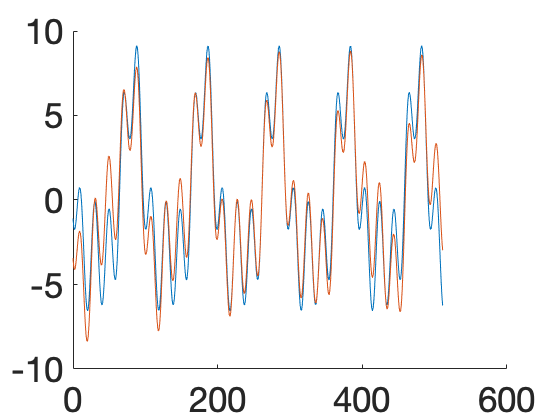

xr = zeros(M,1);
for p = 1:3
    xr = xr + magpks(p)*exp(1i*angpks(p))*exp(1i*fpks(p)*n);
    %xr = xr + magpks(p)*cos(angpks(p)+fpks(p)*n);
end 
xr = real(xr);

figure;
hold on;
set(gca,'FontSize',35);
plot(0:M-1,x);
plot(0:M-1,xr);

I have no fucking clue about what is going on, but it seems a little better.

## PErguntas

G´afico de mag é assim ou corta-se metade?

Dividimos por M ou por N a dft?